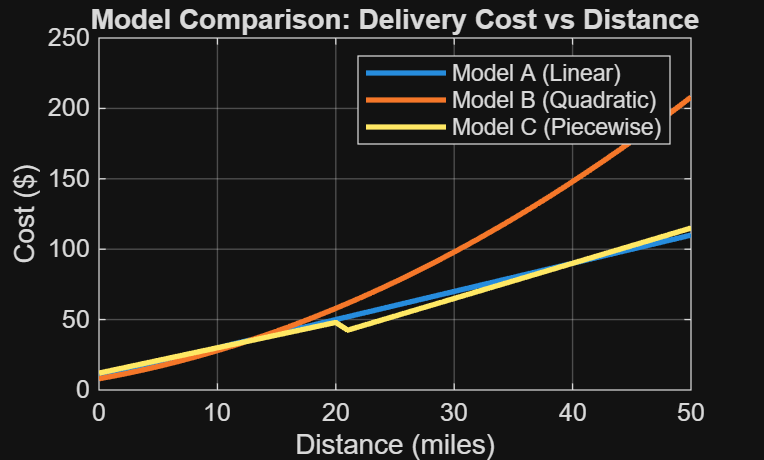

% Zulaikha Khan 
% ES 115 Engineering Computer Applications 
% Model Selection Challenge 
% Instructor: Lynroy Grant 
% March 28, 2026 
 
clear; clc; close all; 
 
% ---------------------------- 
% Scenario: Delivery Cost vs Distance 
 
x = 0:1:50; % distance (miles) 
 
% ---------------------------- 
% Model A: Linear 
% Constant rate + base fee 
A = 2*x + 10; 
 
% ---------------------------- 
% Model B: Quadratic 
% Cost increases faster at longer distances 
B = 0.05*x.^2 + 1.5*x + 8; 
 
% ---------------------------- 
% Model C: Piecewise Linear 
C = zeros(size(x)); 
 
% Short distances 
C(x <= 20) = 1.8*x(x <= 20) + 12; 
 
% Long distances 
C(x > 20) = 2.5*x(x > 20) - 10; 
 
% ---------------------------- 
% Plot all models 
figure; 
plot(x, A, 'LineWidth', 2); hold on; 
plot(x, B, 'LineWidth', 2); 
plot(x, C, 'LineWidth', 2); 
 
title('Model Comparison: Delivery Cost vs Distance'); 
xlabel('Distance (miles)'); 
ylabel('Cost ($)'); 
legend('Model A (Linear)', 'Model B (Quadratic)', 'Model C (Piecewise)'); 
grid on; 